export_graphics = true;

u = linspace(0, 1, 21);

functionals = {
    @fun_length, 'Length';
    @(Bx, By, u, v) 0.7 * fun_area(Bx, By, u, v) + 0.3 * fun_orthogonal2(Bx, By, u, v), 'Area';
    @fun_orthogonal, 'Orthogonality-I';
    @fun_orthogonal2, 'Orthogonality-II';
    @fun_orthogonal3, 'Orthogonality-III';
    @fun_orthogonalA, 'Area orthogonality';
    @fun_uniformity, 'Uniformity';
    @fun_eccentricity, 'Eccentricity';
    @fun_liao, 'Liao';
    @fun_winslow, 'Winslow';
    @fun_modified_liao, 'Modified Liao';
    @fun_oddy, 'Oddy'
    };

Bx1 = [-0.5 -1.5 -1.5 -0.5; 1 1 1 1; 2 2 2 2];
By1 = [-2.7 -0.5 0.5 2.7; -1 -0.5 0.5 1; -1 -0.5 0.5 1];

Bx2 = [2 2 2 2; 3 3 3 3; 4.5 5.5 5.5 4.5];
By2 = [-1 -0.5 0.5 1; -1 -0.5 0.5 1; -2.7 -0.5 0.5 2.7];

Bx2(2, :) = 2*Bx1(end, :) - Bx1(end-1, :);
By2(2, :) = 2*By1(end, :) - By1(end-1, :);

[bx1, by1] = coons_patch(Bx1, By1);
[bx2, by2] = coons_patch(Bx2, By2);

[bx1, by1, bx2, by2] = normalize_points2(bx1, by1, bx2, by2);

inner_x1 = Bx1(2:end-1, 2:end-1);
inner_y1 = By1(2:end-1, 2:end-1);
border_x = Bx1(end, 2:end-1);
border_y = By1(end, 2:end-1);
inner_x2 = Bx2(3:end-1, 2:end-1);
inner_y2 = By2(3:end-1, 2:end-1);

x_init = [inner_x1(:); inner_y1(:); border_x(:); border_y(:); inner_x2(:); inner_y2(:)];

random_perturbation = randn(size(x_init));
m = max(abs(random_perturbation(:)));

x_init = x_init + (0.1 / m) * random_perturbation;

for i = 1:size(functionals, 1)
    func = functionals{i, 1};
    name = functionals{i, 2};

    [bx1, by1, bx2, by2] = optimizerC1(x_init, bx1, by1, bx2, by2, u, u, func);

    [b1, b2, b3] = bezier2(bx1, by1, zeros(size(bx1)), u, u);
    [c1, c2, c3] = bezier2(bx2, by2, zeros(size(bx2)), u, u);

    figure
    surf(b1, b2, b3, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
    hold on
    surf(c1, c2, c3, 'FaceColor', 'None', 'EdgeColor', '#5EE3FF');

    grid off
    set(gca, 'visible', 'off')
    view([-0.50 90.00])

    filename = sprintf('example1_%s.pdf', name);

    if export_graphics
        exportgraphics(gcf, filename, 'ContentType', 'vector')
    end
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


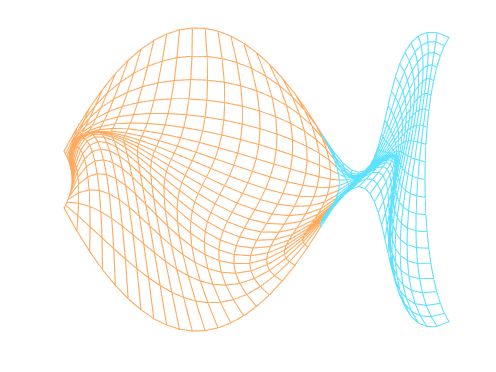


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


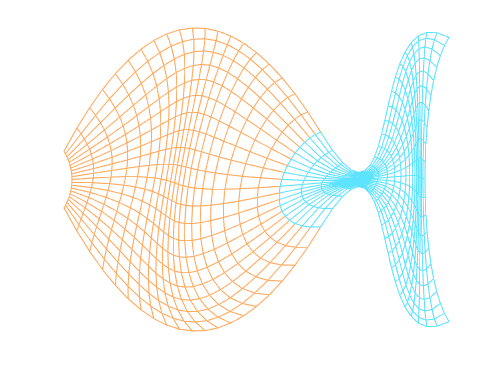


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


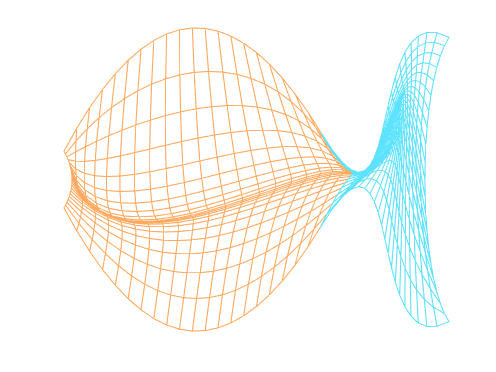


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


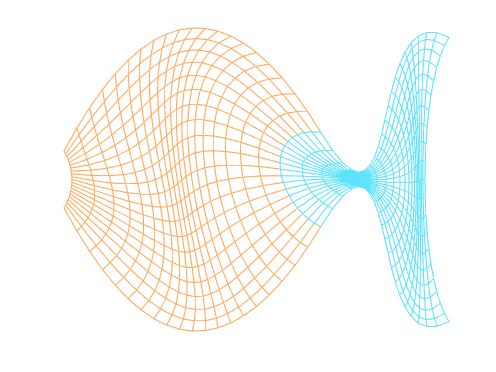


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


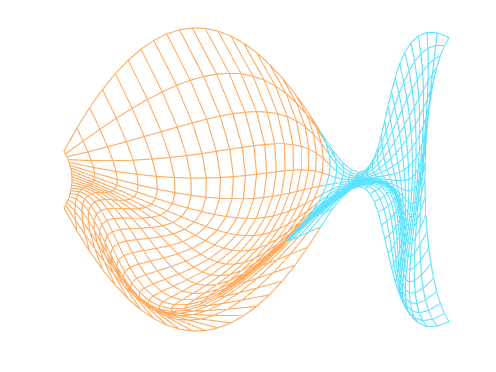


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


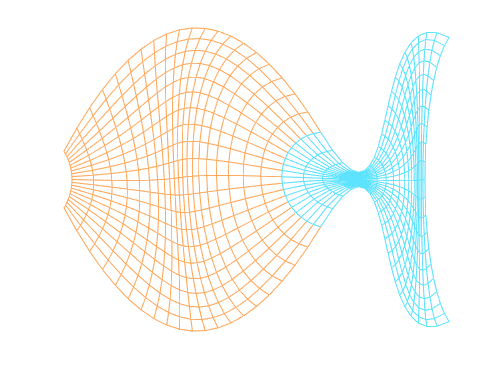


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


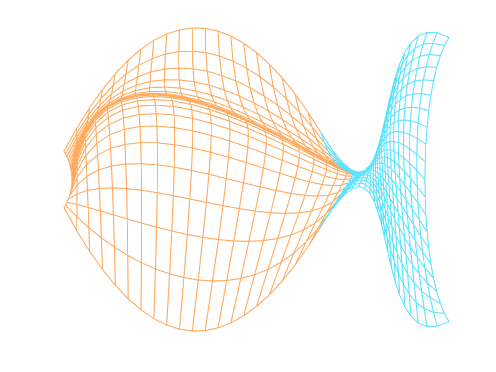


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


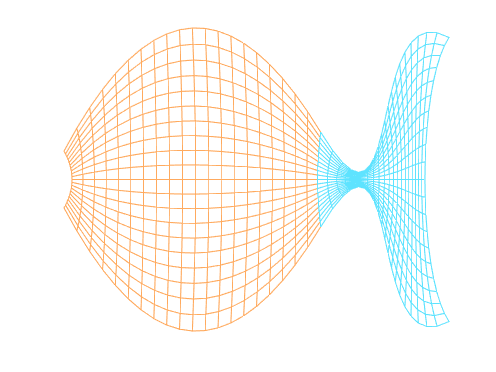


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



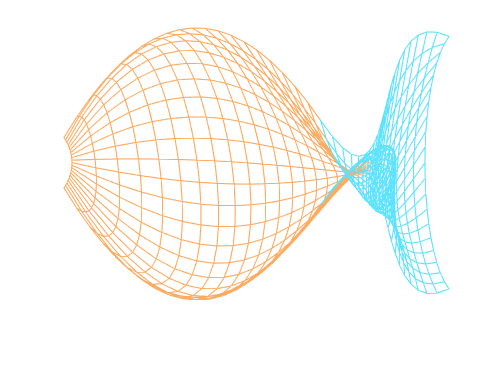


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+05.



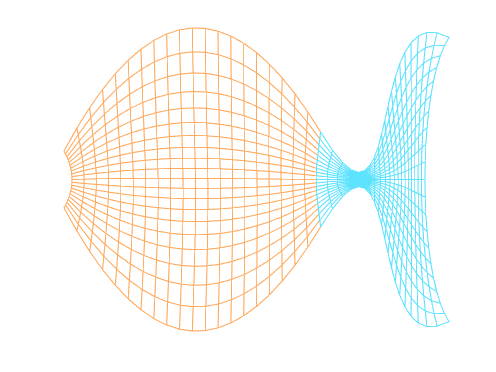


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



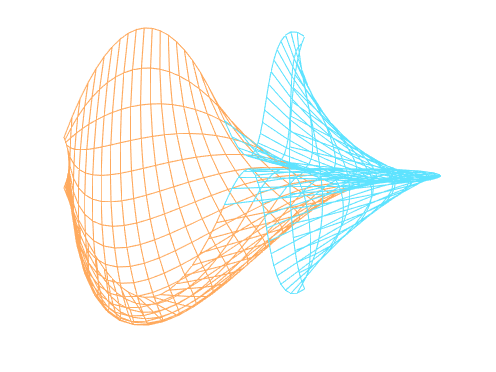


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+05.



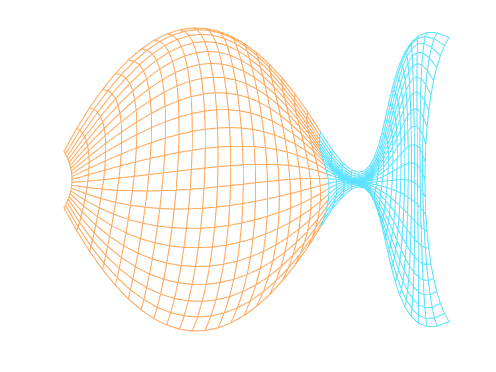

Bx1 = [-8 -7 -7 -8; 0 0 0 0; 8 8 8 8; 16 16 16 16];
By1 = [-0.3 -0.1 0.1 0.3; -2 -2 2 2; -2 -2 2 2; -0.5 -0.3 0.3 0.5];

Bx2 = [16 16 16 16; 18 18 18 18; 20 22 22 20; 28 25 25 28];
By2 = [-0.5 -0.3 0.3 0.5; -2 -2 2 2; -2 -2 2 2; -1.5 -1 1 1.5];

Bx2(2, :) = 2*Bx1(end, :) - Bx1(end-1, :);
By2(2, :) = 2*By1(end, :) - By1(end-1, :);

[bx1, by1] = coons_patch(Bx1, By1);
[bx2, by2] = coons_patch(Bx2, By2);

[bx1, by1, bx2, by2] = normalize_points2(bx1, by1, bx2, by2);

inner_x1 = Bx1(2:end-1, 2:end-1);
inner_y1 = By1(2:end-1, 2:end-1);
border_x = Bx1(end, 2:end-1);
border_y = By1(end, 2:end-1);
inner_x2 = Bx2(3:end-1, 2:end-1);
inner_y2 = By2(3:end-1, 2:end-1);

x_init = [inner_x1(:); inner_y1(:); border_x(:); border_y(:); inner_x2(:); inner_y2(:)];

random_perturbation = randn(size(x_init));
m = max(abs(random_perturbation(:)));

x_init = x_init + (0.1 / m) * random_perturbation;

for i = 1:size(functionals, 1)
    func = functionals{i, 1};
    name = functionals{i, 2};

    [bx1, by1, bx2, by2] = optimizerC1(x_init, bx1, by1, bx2, by2, u, u, func);

    [b1, b2, b3] = bezier2(bx1, by1, zeros(size(bx1)), u, u);
    [c1, c2, c3] = bezier2(bx2, by2, zeros(size(bx2)), u, u);

    figure
    surf(b1, b2, b3, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
    hold on
    surf(c1, c2, c3, 'FaceColor', 'None', 'EdgeColor', '#5EE3FF');

    grid off
    set(gca, 'visible', 'off')
    view([-0.50 90.00])

    filename = sprintf('example2_%s.pdf', name);

    if export_graphics
        exportgraphics(gcf, filename, 'ContentType', 'vector')
    end
end